# Control Flow Structures - Loop Structures - Part 1

 Do I have to have MATLAB installed on my computer right now? No, you can use  [MALAB Online](https://matlab.mathworks.com/)!

## **What we covered last week**

Last week we learnt about, 

- What arrays and matrices are 

- Creating arrays 

- Indexing into arrays  

- Concatenation of arrays 

- Operating with function on arrays 

- Introduction to decision making with operators  

- Relational operators 

- Logical operators 

## **Introduction**

In programming, a control flow is the order in which individual statements, instructions or function calls of a piece of code are executed or evaluated. An integral part of programming beings  with understanding how to automate the process of running/executing an algorithm. This lesson will be split into two parts: part 1 and part 2. In part a we go over the fundamental loop structures in MATLAB and how to use them, we will also touch on vectorisation as a way to create computationally efficient code.

## **Loop Structures**

Loops are control instructions that are commonly used for **iteration** and **repetition**. For example, given a list of names such as ["John", "Freddy", "Lisa"], you may want to print out each of the names in the list so that they appear on the MATLAB command window. This could be manually achieved by using a built-in function in MATLAB called [disp](https://www.mathworks.com/help/matlab/ref/disp.html)() to display all 3 names on the MATLAB command window. 

disp("John")
disp("Freddy")
disp("Lisa")

Considering that the list only has 3 names, this is easily achievable. However, consider a case where our list has 10 names, whilst you may still be able to get away with manually displaying all 10 names, it is easy to see how tedious this process can be as our list gets bigger. Loop control instructions can be used to automate the process of iteratively calling all names sequentially in a given list without the need for manually calling each name individually from the list. There are 2 main loop controls that are supported in MATLAB, namely **for loops** and **while loops**.

### For Loops

For loops are used for iterating over a sequence such as an array, a set or a string. For loops are used in instances where an algorithm needs to be repeated for a specified number of times, and only stopping once the ideal number of iterations has been reached. The common structure if a for loop is specified as follows: 

                                                                                 *                                              for i = ****v***

*          loop body*

*                                                                                                                               end*

All For loop statements begin with the keyword "for”, followed by what is called an iteration variable (in this example, i) which represents each of our list items at a single time. This variable is set equal to our list (**v**) which in this example contains a list of names. The loop body contains the instruction that will be repeated for all elements in the list. Finally, the loop is closed by using the keyword "end". It should be noted that for loops in MATLAB require the "end" declaration at the end of the loop body to complete the structure of a for loop.  

The standard process begins at the iteration variable where an element from the list is taken into the loop body where a set of instructions are executed on the variable, this process happens iteratively for all elements in the list. In our names example this would look like this,

In this example we will create an array with 3 names, refer to week 2 to learn more about how to create different arrays. Using square  brackets [] will give an array whilst {} brackets will give a cell array. All elements in array related brackets [] must be of the same data type and elements in a cell array {} can have different data types.

for i = ["John", "Freddy", "Lisa"]
    disp(i)
end

For loops can be used with different data structures. For example, a for loop can be used to sum numbers in an array.

Now you try! In the line below, using a **for loop statement**, find the sum of the array "numbers" and assign it to the variable "counter".

numbers = [2, 4, 6];
counter = 0;


### While Loops

While loops are another kind of loop structure. Whilst for loops can be used unconditionally (without a condition), while loops can be iterated based on a specified condition. For example, given a list of numbers, you may want to sum the first 10 numbers on the list with summing all elements in the list. The common structure of a while loop is specified as follows

                                                                                                                             *              while (****condition****)*

*loop body*

*                                                                                                                                            end*

The keyword for starting a while loop is "while" followed by a condition which will terminate the loop but otherwise continue unless the condition has been met. This is followed by the loop body where a set of instructions are executed and just like the for loop, an "end" keyword is used to close the while loop. An example is given as follows, 

In the for loop example, an iteration variable "i" was used based on the elements of a list, however, in the above example, the while loop uses an independent variable that is initialised to 0. The condition in the while loop states that if the independent variable is less than 10, the variable will be incremented by 1. This while loop terminates once the independent variable goes over 10.  

The idea of using a loop structure can be greatly appreciated in numerical computations where usually the same piece of code is repeatedly executed. In real world applications, the error of repeatedly executing a piece of code can be reduced by using a loop structure. Loops can be nested in MATLAB. The for loops can be nested within while loops, and vice versa. To finish a loop, there should be a matching end statement. 

Now you try! In the line below, using a while loop statement, individually display the apples element in the "fruits" array.

fruits = ["apricot", "pears", "pineapples", "apples"];


Some notable differences between for loops and while loops are given in the table below, 

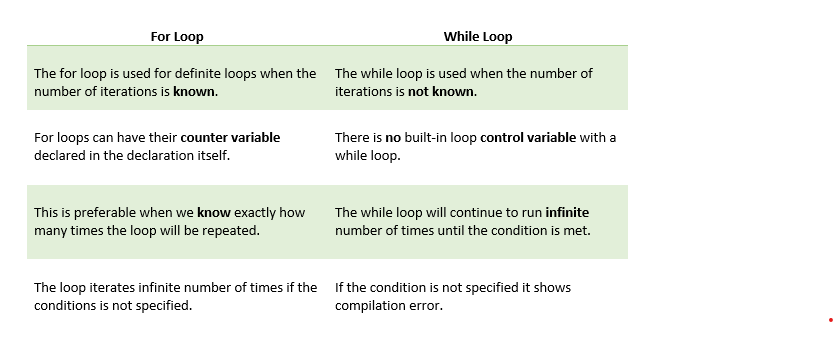

## Vectorized Approach

So far the given examples of the different loop structures have been reasonably simple, however, loops can often be used to build complex algorithms that can result in the overall execution of the algorithm slowing down. Using a vectorized approach can sometimes assist with the computational speed of an algorithm  by considering a matrix or a vector as a whole object thus removing the need for loops. This increases the efficiency of a piece of code. 

 Given a vector of radii of various circles, ***r ***= [1, 1.2, 0.9, 0.7, 0.85, 0.9, 1.12, 0.56, 0.98], we can use vectorisation to compute the area of the various circles ($\pi r^2$).

If we used a for-loop statement, we would represent the solution as in the example pseudo-code;

however, using the vectorisation method we can directly compute each circle area from the corresponding radius in the array using dot notation (.) represented in the pseudo-code;

Now you try! Given the side lengths of various squares, use vectorisation to calculate the area of the various squares($a^2$).  Fill in the notation in the space below.

a = [3, 6, 9];


In the example below,  a concept called pre-allocation is used. For and While loops that incrementally increase the size of a data structure each time through the loop can adversely affect performance and memory use. Repeatedly resizing arrays often requires MATLAB to spend extra time looking for larger contiguous blocks of memory, and then moving the array into those blocks. Often, you can improve code execution time by pre-allocating  the maximum amount of space required for the array.

tic
cubeSurfaceArea = zeros(1, length(a)); % Pre-allocation
for i = 1:length(a)
    cubeSurfaceArea(i) = 6*a(i)^2;
end
cubeSurfaceArea
toc

However, using vectorisation is a much more preferred way. It eliminates the need for pre-allocation and speeds up the execution time of a piece of code. 

tic
cubeSurfaceArea = 6*a.^2;
toc

As can be seen by the time taken to execute both examples, the vectorised method is time efficient compared to the for-loop structure. 

## Part 1 Summary

- Loop structures can be used to automate the process of repeating an instruction.

- There are two kinds of loop structures: For loops and While loops. 

- For loops can be used when the number of iterations is known and While loops can be used when the number of iterations is not known.

- Vectorization  can be used to replace loops where each element in an object (i.e array) is treated as a whole object. 

## **PowerPoint Presentation**

- [Week_3_Part_1_ControlFlowStructures.pptx](matlab:open('..\PowerPoint Presentations\Week_3_Part_1_Control_Flow_Structures.pptx'))